# Getting started with Iterative data display

This script demonstrates the benefits of using the `iterativeDisplay` instead of normal Matlab functions.

Benefits: much faster display of curves, limited programming impact

Limitations: 

- one call to a function can only generate one line, surface, etc. 

- not all the graphics functions are yet supported. 

- it is not possible to specify a target axes for title, xlabel, ylabel, zlabel, etc.

- command line instructions cannot be used : instread of `hold on`, you must use `hold('on')`. Also apply for the `grid` instruction.

## Demonstration

### Basic usage

The first step is to create a new figure and define the object

figure;
id=iterativeDisplay();

This object is intended to be used in a loop that performs the same graphic operations exactly in the same plotting operation order at every iteration.

So in you loop, you will need to start a new iteration. The result is that the `iterativeDisplay` object will record all the successive graphic operations until the next iteration.

id.newIteration();

 To use it, you simply need to add "`id`" in front of the matlab graphic instruction. You may notice that the `legend` instruction does not have any effect. This is part of the optimization: updating the legend object at every iteration is really slow. As a result, the legend is only displayed during the final iteration.

id.plot(rand(1,10));
id.hold('on');
id.plot(1:2:20,rand(1,10));
id.grid('on');
id.legend('1st curve','2nd curve');

In a loop, the previous code would be iterated. As an illstration, we are going to reproduce the secord iteration of the loop manually.

So the second iteration is started by calling the `newIteration` method. The result is that now, the object is placed in the "`iter`" mode. In this mode, all the `plot`, `semilogx`, `surf`, etc objects are automatically updated instead of being created again. This is one of the major source of improvement. 

id.newIteration();

 Now, the second iteration is performed. We just have to run the exact same code. The sofware will automatically switches between the object creation mode to update mode. 

id.plot(rand(1,10));
id.hold('on');
id.plot(1:2:20,rand(1,10));
id.grid('on');
id.legend('1st curve','2nd curve');

In a normal program, the loop would iterate as many times as needed. Then before the final iteration, we need to call the "`finalIteration`" method to allows the `iterativeDisplay` object to perform the final operation such as displaying the legend.

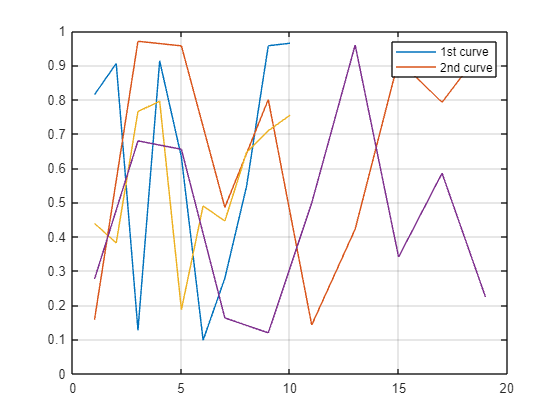

id.finalIteration();
id.plot(rand(1,10));
id.hold('on');
id.plot(1:2:20,rand(1,10));
id.grid('on');
id.legend('1st curve','2nd curve');

As a result, the legend is now displayed.

## Benchmark

### Considered problem

Imagine that we want to perfom $n=1000$ iterations to display the result of some iterative algorithms. Here we will simply display several sine waves with random amplitudes and phases.

clear all;close all;clc;
n=30;      % Number of iterations
m=5;        % Number of curves per tile
tiles=[3 3]; % Tile setup
nsample=500; % number of samples

% Pre-compute time vector
time=linspace(0,1,nsample);

% genreate fake legends
lgd=cell(1,m);
for i=1:m
    lgd{i}=num2str(i);
end

### Classic programming

Here is the bad way of doing this. The only advantage is the simplicity of the code.

So basically, the all the axes are deleted at every iteration and rebuild to update the data.

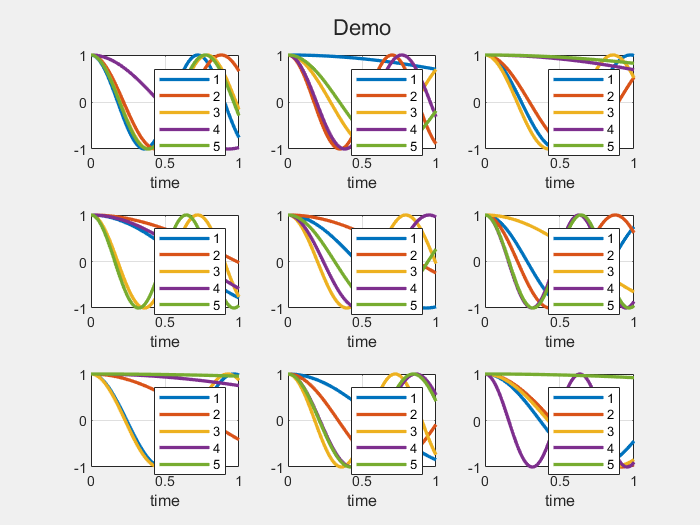

figure;
set(gcf,'Visible','on')
rng(42); % To ensure result reproductibility
h=tiledlayout(tiles(1),tiles(2));
set(h.Title,"String",'Demo');
tic
for noIter=1:n
    for noTile=1:tiles(1)*tiles(2)
        nexttile(noTile); % Select tile
        
        % Erease tile
        cla;
       
        % Plot the m requested curves
        for k=1:m
            % Generate fake data
            w=rand*10;
            y=cos(w*time);
            % Plot data
            plot(time,y,'linewidth',2);
            hold('on');
            grid('on')
            xlabel('time');
        end
        % Update legend
        legend(lgd);
    end
    % All the data has been updates, force figure refresh
    drawnow;
end

% Memorize duration time
classicCodeDuration=toc;

### Using the iterativeData object

The proposed approach does not requires a lot of modification to your code. 

First, we need to create an `iterativeDisplay` object.

id=iterativeDisplay();

At the first iteration, we will set its status to 1. This indicates that the display is being built for the first time. The object will record all the necessary information for future internal usage.

For the remaining iteration execept the last one, we set the status to 2 to indicate that we would like an optimized update of existing graphic object.

Finally, during the last iteration, we set the status to 3 to display the legend, axis, etc. This allows producing a nice final figure;

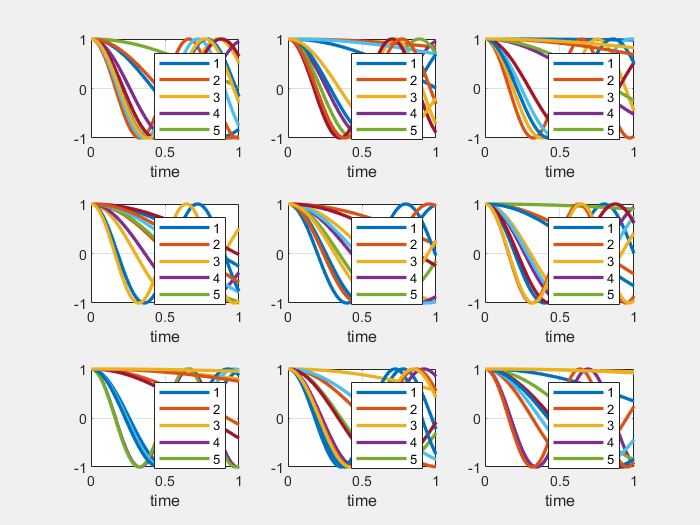

clf;
rng(42); % To ensure result reproductibility
h=id.tiledlayout(tiles(1),tiles(2));
id.set(h.Title,"String",'Demo');

tic
for noIter=1:n
    % Added code for indicating a new iteration
    if noIter<n
        id.newIteration;
    else
        id.finalIteration;
    end
    % Code remains the same except "id." in front of graphic command.
    for noTile=1:tiles(1)*tiles(2)
        % Select tile
        id.nexttile(noTile); 
        
        % The "cla" is not needed as we keep the same graphic objects and
        % will update their propertis
        % cla 

        % Plot the m requested curves
        for k=1:m
            % Generate fake data
            w=rand*10;
            y=cos(w*time);

            id.plot(time,y,'linewidth',2);
            id.hold('on');
            id.grid('on');
            id.xlabel('time');
        end
        % Update legend
        id.legend(lgd);

    end
    % All the data has been updates, force figure refresh
    drawnow;
end

optimizedCodeDuration=toc;
fprintf('Classic code duration : %.2f seconds\n',classicCodeDuration);

Classic code duration : 14.63 seconds


fprintf('Optimized code duration : %.2f seconds\n',optimizedCodeDuration);

Optimized code duration : 1.00 seconds
